clear ;
close all;

load ryan2_gen_data_new.mat

cap = zeros();
Vd = zeros();
%Vd = [1:100];
battery_dataset_new(1).QDischargeSmooth

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


battery_dataset_new(1).Vd

ans =     2.0166    3.3117    3.2489    3.2148    3.1953    3.1833    3.1754    3.1698    3.1656    3.1623    3.1592    3.1567    3.1545    3.1522    3.1503    3.1484    3.1466    3.1448    3.1431    3.1414    3.1397    3.1379    3.1361    3.1345    3.1327    3.1310    3.1293    3.1276    3.1257    3.1240    3.1220    3.1202    3.1183    3.1163    3.1144    3.1123    3.1103    3.1083    3.1061    3.1040    3.1019    3.0997    3.0975    3.0953    3.0931    3.0908    3.0885    3.0861    3.0838    3.0813
    2.0161    3.3112    3.2485    3.2142    3.1945    3.1829    3.1749    3.1695    3.1653    3.1617    3.1589    3.1563    3.1540    3.1519    3.1499    3.1481    3.1462    3.1444    3.1427    3.1410    3.1392    3.1376    3.1359    3.1342    3.1325    3.1308    3.1291    3.1273    3.1254    3.1236    3.1217    3.1198    3.1179    3.1161    3.1139    3.1121    3.1101    3.1080    3.1059    3.1038    3.1017    3.0994    3.0972    3.0952    3.0927    3.0905    3.0882    3.0859    3.0836   

size(battery_dataset_new(1).QDischargeSmooth)

ans =    428     1


length(battery_dataset_new(1).QDischargeSmooth)

ans = 428

idxAll = (1:length(battery_dataset_new));
idxTrainValid = [ new_idxTrain new_idxValid ];
trainIdxAll = []; %zeros();
validIdxAll = []; %zeros();
testIdxAll = []; %zeros();


j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = battery_dataset_new(i).QDischargeSmooth;
    leng = length(cap_temp);
    %startIndx = j ;
    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = battery_dataset_new(i).Vd ;
    %Vd = [Vd ; Vd_temp];
    if  i == 1
        Vd = Vd_temp;
        cap = cap_temp; 
    else
        Vd = vertcat(Vd,Vd_temp);
        cap = vertcat(cap,cap_temp);
    end
    
    if any(new_idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       trainIdxAll =  [trainIdxAll append_index ] ;
    end
    if any(new_idxValid(:) == i) 
       validIdxAll =  [validIdxAll append_index ] ;

    end
    if any(new_idxTest(:) == i) 
       testIdxAll =  [testIdxAll append_index ] ;

    end
    %Vd(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end
cap

cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


Vd

Vd =     2.0166    3.3117    3.2489    3.2148    3.1953    3.1833    3.1754    3.1698    3.1656    3.1623    3.1592    3.1567    3.1545    3.1522    3.1503    3.1484    3.1466    3.1448    3.1431    3.1414    3.1397    3.1379    3.1361    3.1345    3.1327    3.1310    3.1293    3.1276    3.1257    3.1240    3.1220    3.1202    3.1183    3.1163    3.1144    3.1123    3.1103    3.1083    3.1061    3.1040    3.1019    3.0997    3.0975    3.0953    3.0931    3.0908    3.0885    3.0861    3.0838    3.0813
    2.0161    3.3112    3.2485    3.2142    3.1945    3.1829    3.1749    3.1695    3.1653    3.1617    3.1589    3.1563    3.1540    3.1519    3.1499    3.1481    3.1462    3.1444    3.1427    3.1410    3.1392    3.1376    3.1359    3.1342    3.1325    3.1308    3.1291    3.1273    3.1254    3.1236    3.1217    3.1198    3.1179    3.1161    3.1139    3.1121    3.1101    3.1080    3.1059    3.1038    3.1017    3.0994    3.0972    3.0952    3.0927    3.0905    3.0882    3.0859    3.0836    

x = Vd;
y = cap;
[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);

- FNN1 - 1 layer


new_netFNN1_1 = feedforwardnet([100 50]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
new_netFNN1_1.divideFcn = 'divideind';
new_netFNN1_1.divideParam.trainInd = trainIdxAll;
new_netFNN1_1.divideParam.valInd = validIdxAll;
new_netFNN1_1.divideParam.testInd = testIdxAll; 
    
%new_netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
new_netFNN1_1.trainParam.showWindow = 0; 
new_netFNN1_1.trainParam.epochs = 1;  %300; % 전체 데이타를 300번 반복 이용해라
% https://kr.mathworks.com/help/matlab/matlab_prog/measure-performance-of-your-program.html
tic
[new_netFNN1_1, tr] = train(new_netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 51.073723 seconds.


%tr

% new_netFNN2_1 = feedforwardnet([100]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% new_netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
% new_netFNN2_1.divideParam.trainInd = tr.trainInd;
% new_netFNN2_1.divideParam.valInd = tr.valInd;
% new_netFNN2_1.divideParam.testInd = tr.testInd; 
% 
% new_netFNN2_1.trainParam.epochs = 100; %3100; % 전체 데이타를 300번 반복 이용해라
% new_netFNN2_1.trainParam.show = NaN;
% new_netFNN2_1.trainParam.showWindow = 0;
% new_netFNN2_1 = train(new_netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');


% 시간이 너무 오래 걸린다.
% new_netFNN2_1 = feedforwardnet([100,50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% % new_netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
% 
% new_netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
% new_netFNN3_1.divideParam.trainInd = tr.trainInd;
% new_netFNN3_1.divideParam.valInd = tr.valInd;
% new_netFNN3_1.divideParam.testInd = tr.testInd; 
% 
% % 시간을 줄이기 위해 10으로 바꾸자. 
% new_netFNN3_1.trainParam.epochs = 10; % 300 %100; % 전체 데이타를 300번 반복 이용해라
% new_netFNN3_1.trainParam.show = NaN;
% new_netFNN3_1.trainParam.showWindow = 0;
% new_netFNN3_1 = train(new_netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');
% %view(new_netFNN3_1)

pFNN1_1 = new_netFNN1_1(xnorm(tr.testInd, :)');
%pFNN2_1 = new_netFNN2_1(xnorm(tr.testInd, :)');

ytest = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_1_hat = pFNN1_1 * yrate + ymin;
%pFNN2_1_hat = pFNN2_1 * yrate + ymin;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = NaN

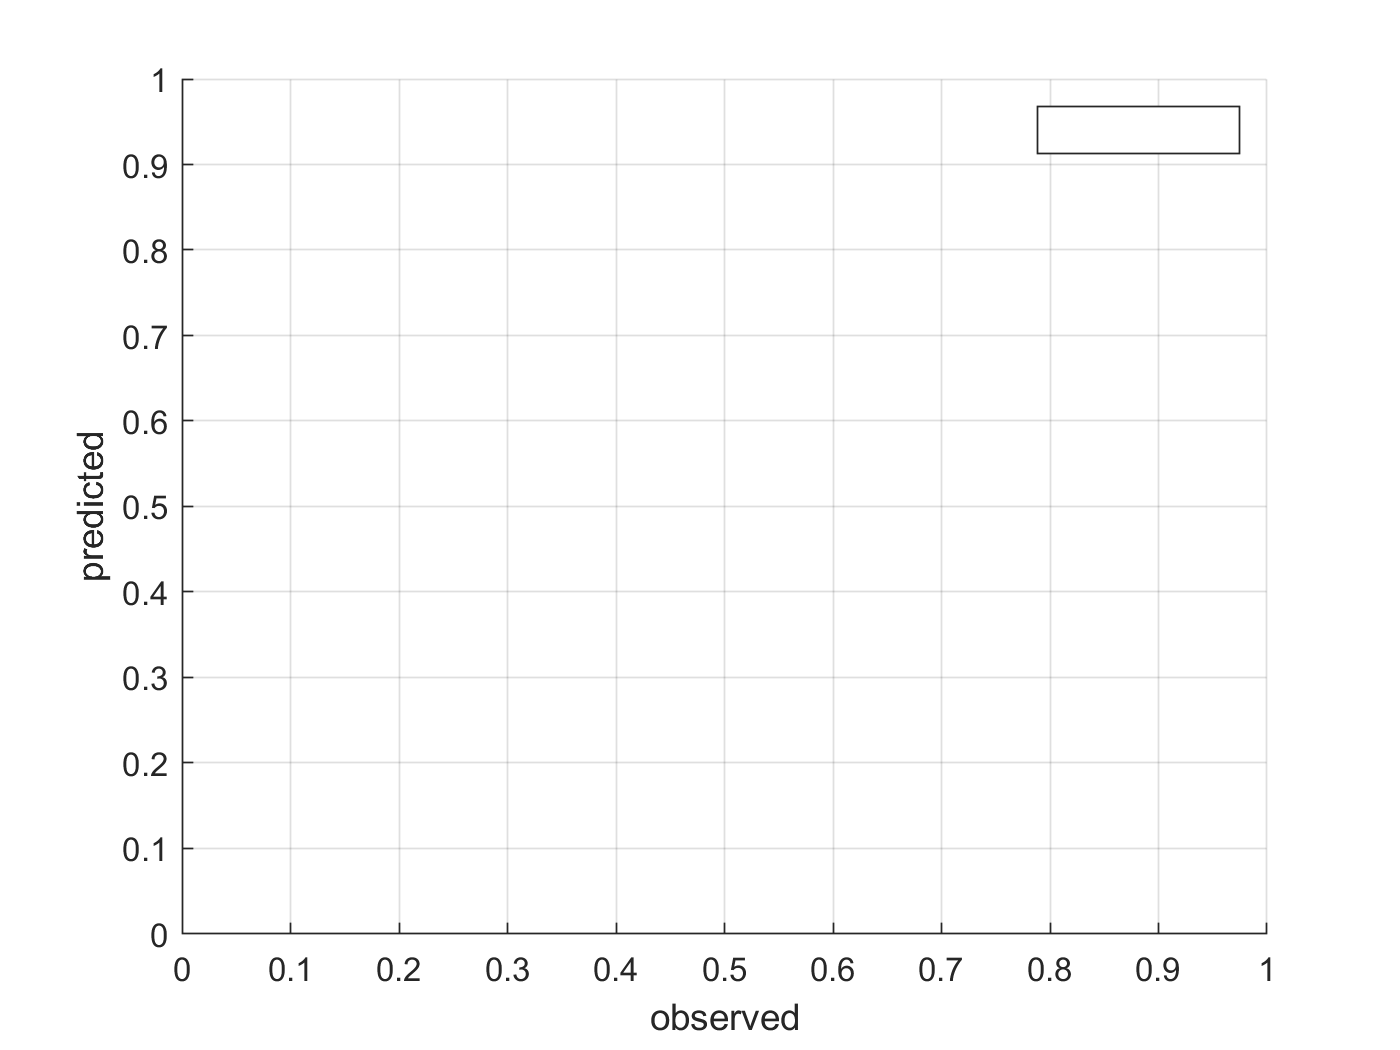

%rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
%plot(ytest,pFNN2_1_hat,'_')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat')


%		'pFNN2_1_hat')



battery_dataset =  battery_dataset_new;
netFNN2_100_50 = new_netFNN1_1;
ryan3_gen_data_model_new_desc = 'ryan3_gen_data_model_new';
save('ryan3_gen_data_model_new.mat','ryan3_gen_data_model_new_desc')
save('ryan3_gen_data_model_new.mat','netFNN2_100_50' ,'-append')

%save('ryan2_gen_data_model_new.mat','new_netFNN2_1' ,'-append')


pFNN1_1_self = new_netFNN1_1(xnorm([tr.trainInd tr.valInd], :)');
%pFNN2_1_self = new_netFNN2_1(xnorm([tr.trainInd tr.valInd], :)');

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pFNN1_1_self_hat = pFNN1_1_self * yrate + ymin;
%pFNN2_1_self_hat = pFNN2_1_self * yrate + ymin;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 135.5486

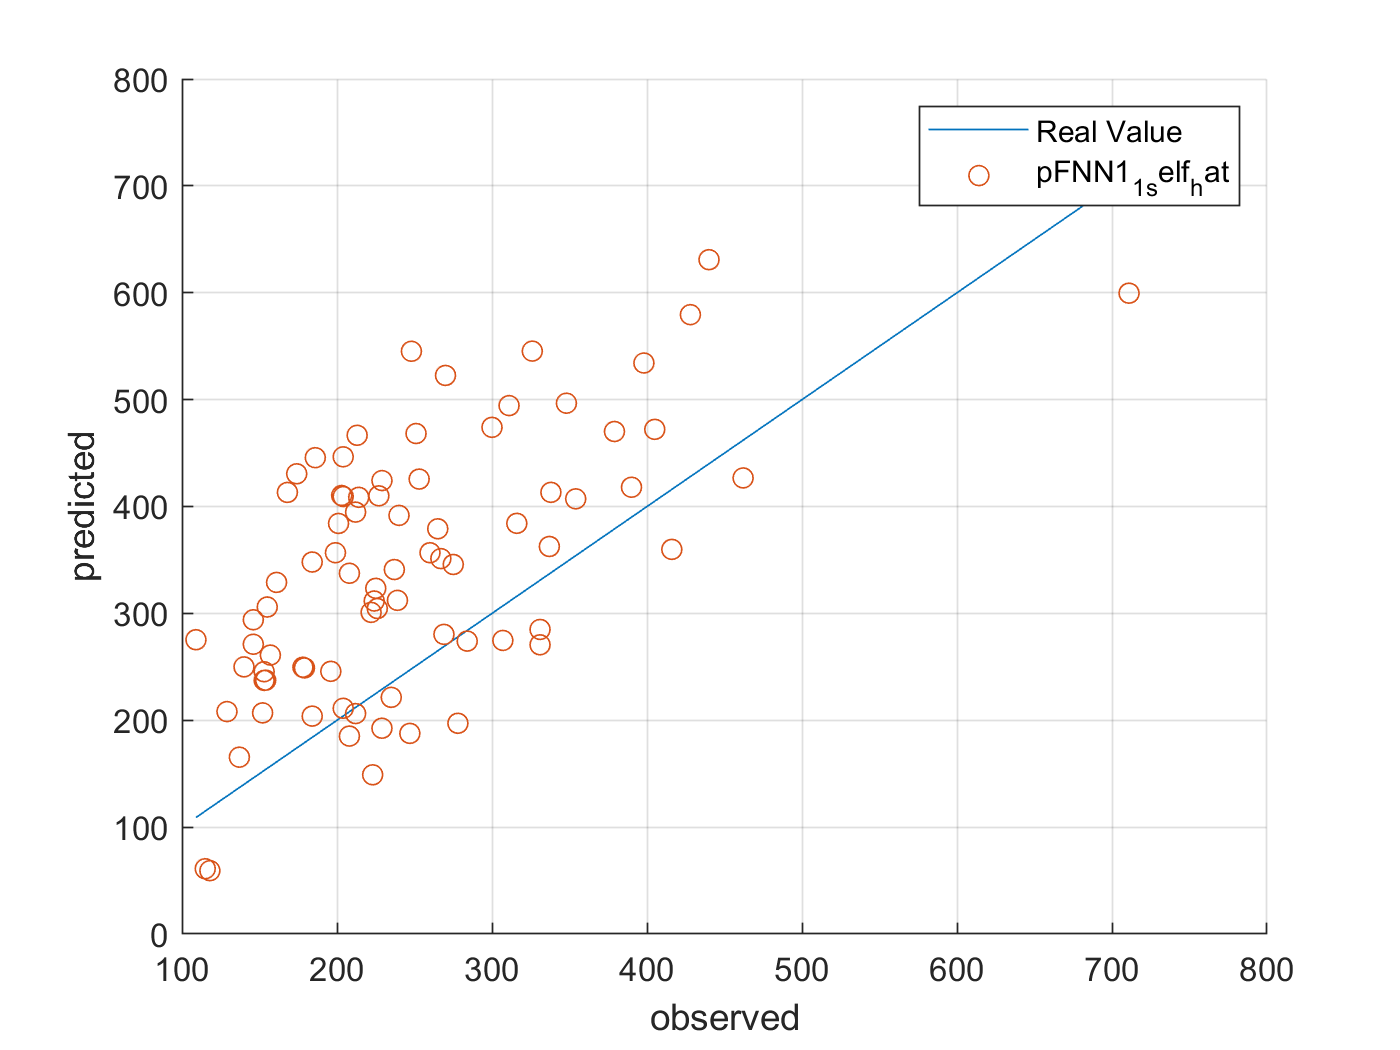

%rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
%plot(ytrain_self,pFNN2_1_self_hat,'_')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat')

%		'pFNN2_1_self_hat')
